# Hands-On: Power Spectra & Spectral Factorization

## Spectral Factorization

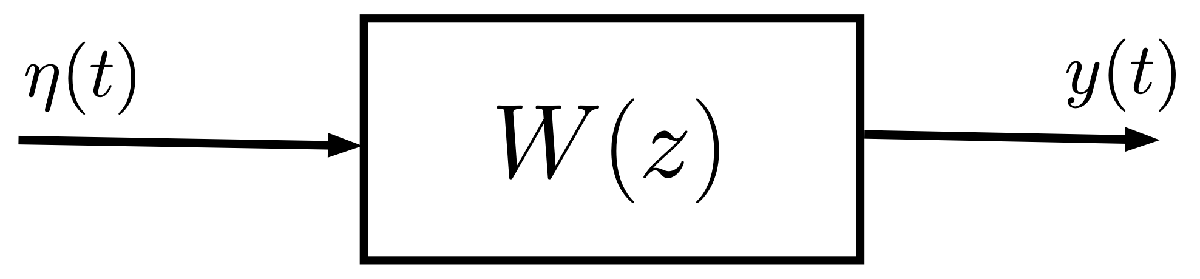

A stationary stochastic process $y(t)$ has the power spectrum


$$\Gamma_y(\omega) = \displaystyle \frac{50}{29-20\,\cos (\omega)$$


Find the LTI filter $W(z)$ that creates $y(t)$ by filtering the white noise $\eta(t)$, and find the variance of the white noise $\sigma^2_{\eta}$.

**Hint**: analyse and reuse the code in [this live script](matlab:open('./L8_SpectralFactorization.mlx')).

clear 
close all
clc

syms omega
Gamma_y = (50)/(29-20*cos(omega))

$$Gamma\_y = -\frac{50}{20\,\cos\left(\omega \right)-29}$$

Varianza processo y:

sigma2_y =  ( (1/(2*pi))*int(Gamma_y,omega, [-pi,pi] ));
sigma2_y_ALT =  double(sigma2_y)

sigma2_y_ALT = 2.3810

Sigma2Y = sym(sigma2_y_ALT)

$$Sigma2Y = \frac{50}{21}$$

Gamma_y = rewrite(Gamma_y, "exp") 

$$Gamma\_y = -\frac{50}{10\,{\mathrm{e}}^{-\omega \,\mathrm{i}}+10\,{\mathrm{e}}^{\omega \,\mathrm{i}}-29}$$

syms z

PhiZ = subs(Gamma_y, exp(1i*omega), z)

$$PhiZ = -\frac{50}{10\,z+\frac{10}{z}-29}$$

Trick:

syms x
PhiX = subs(PhiZ,(z+z^(-1)), x) % the first step of the trick: substituting the expression

$$PhiX = -\frac{50}{-29+10\,x}$$

% the second step of the trick: get numerator and denominator of the
% symbolic expression PhiX
[betaX, alphaX] = numden(PhiX)

$$betaX = -50$$

$$alphaX = -29+10\,x$$

betaPoly = sym2poly(betaX) % the coefficients of the numerator of the spectrum, as a symmetric polynomial

betaPoly = -50

% betaPoly contains the floating-point description of the coefficients, 
% from the highest to the lowest degree monomial of the auxiliary variable x
alphaPoly = sym2poly(alphaX) % the coefficients of the denominator of the spectrum, as a symmetric polynomial

alphaPoly =     10   -29


% alphaPoly contains the floating-point description of the coefficients, 
% from the highest to the lowest degree monomial of the auxiliary variable x

Applicazione

[r, Cz_coeffs, Az_coeffs] = L8_spectrFactAlg(betaPoly, alphaPoly)

r = 2

Cz_coeffs = 1

Az_coeffs =     1.0000   -0.4000


Now rewrite the result as symbolic rational function

% sort the display output of polynomial function in ascending order, i.e.
% according to the order of each monomial term
sympref('PolynomialDisplayStyle','ascend');

syms z1 % a trick to represent in a compact way 1/z

lambda2xi = sym(r) % the white noise spectrum

$$lambda2xi = 2$$

Az1 = poly2sym(fliplr(Az_coeffs), z1) % the polynomial A(z) 

$$Az1 = 1-\frac{2\,z_{1}}{5}$$

Az = subs(Az1,z1,z^(-1))

$$Az = 1-\frac{2}{5\,z}$$

Cz1 = poly2sym(fliplr(Cz_coeffs), z1) % the polynomial C(z) 

$$Cz1 = 1$$

Cz = subs(Cz1,z1,z^(-1))

$$Cz = 1$$

Wz = Cz1/Az1 % the LTI system transfer function as symbolic object

$$Wz = -\frac{1}{-1+\frac{2\,z_{1}}{5}}$$

W_z = tf(Cz_coeffs, Az_coeffs, 1, 'Variable','z^-1')

W_z =
 
       1
  ------------
  1 - 0.4 z^-1
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


la varianza del rumore bianco è:

(2/5)^2

ans = 0.1600